# Density profiles from tilt measurements

M.P.Ross

## Earthquake Event:

The following analysis is done on a single earthquake with the plan to include a large set of earthquakes in the future to allow for better estimation of geophyisical parameters. The event was the M6.7 earthquake 120km NW of Olonkinbyen, Svalbard and Jan Mayen (near Iceland) measured at the LIGO Livingston Observatory using a STS-2 seismometer and two BRSs developed by the Eöt-Wash group at the Univserity of Washington.

## Properties of Rayleigh Waves:

Elastic seismic waves have six independent component, three translational $(u_x, u_y, u_z)$ and three rotational$(\theta_x,\theta_y,\theta_z)$. Traditional seismology only utilizes the three translational components but with the development of devices that sense purely the rotational degrees of freedom new information is available. Below are equations for the six components of a plane Rayleigh wave in a flat half space [1]:


$$u_x({\bf r} ,t)=\alpha sin(\zeta) cos(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
u_y({\bf r} ,t)=\alpha sin(\zeta) sin(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
u_z({\bf r} ,t)=\alpha cos(\zeta) cos(\omega t-{\bf k}\cdot{\bf r}+\pi/2 + \phi)\\
\\
\theta_x({\bf r} ,t)=\frac{\partial u_z}{\partial y}=\alpha \kappa cos(\zeta) sin(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
\theta_y({\bf r} ,t)=-\frac{\partial u_z}{\partial x}=-\alpha \kappa cos(\zeta) cos(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
\theta_z({\bf r} ,t)=\frac{1}{2}\Big(\frac{\partial u_y}{\partial x}-\frac{\partial u_x}{\partial y}\Big)=0$$


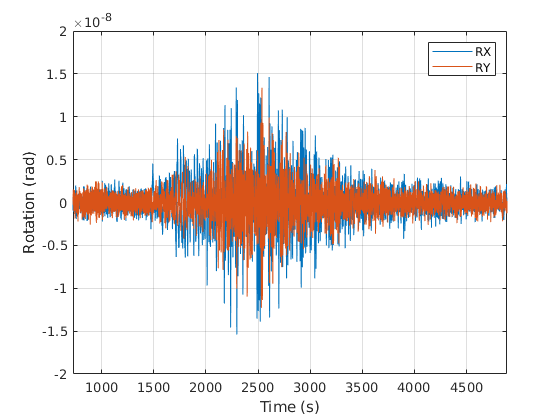

velocityProfileDataLoad;

plot(time,RX,time,RY);
grid on
legend('RX','RY')
xlabel('Time (s)')
ylabel('Rotation (rad)')
xlim([min(time) max(time)])

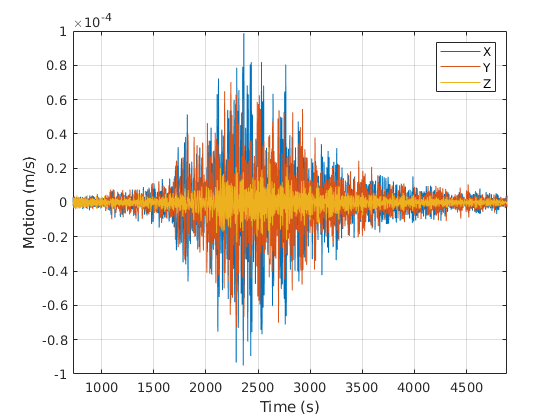

plot(time,X,time,Y,time,Z);
grid on
xlabel('Time (s)')
ylabel('Motion (m/s)')
legend('X','Y','Z')
xlim([min(time) max(time)])

Due to the complex nature of earthquake events, true seismic measurements are far from individual plane waves. However, if we decompose the measured signal into the Fourier domain we get simple equations for the amplitudes at a given frequency:


$$\dot{u_z}=\alpha \omega cos(\zeta)\\
\theta_x=\alpha \kappa cos(\zeta) sin(\psi)\\
\theta_y=\alpha \kappa sin(\zeta) cos(\psi)\\$$


Where the dot represents the time derivative. These can be easily recast into geologically interesting parameters, the Rayleigh wave phase velocity $\nu$ and the angle of incidence $\psi$ of the seismic wave. Here we will only analyze the phase velocity since this encoded the local density profile.


$$\nu\equiv \frac{\omega}{\kappa}=\frac{\dot{u_z}}{\sqrt{\theta_x^2+\theta_y^2}}\\
\psi=arctan\frac{\theta_x}{\theta_y}$$


The transient nature of these events complicates the ability to accurately estimate amplitudes using Discrete Fourier Transforms. Using the method of fitting narrowly bandpassed sets to a sine and cosine allows us to side step this issues while allowing us to use the distribution of the fit amplitudes to estimate the error.

%% Spectra
avg=9;
[ARY, ERY, ~, RY_list] = ampExtraction(RY, sampF);
[ARX, ERX, ~, RX_list] = ampExtraction(RX, sampF);
[AX, EX, ~, X_list] = ampExtraction(X, sampF);
[AY, EY, ~, Y_list] = ampExtraction(Y, sampF);
[AZ, EZ, F, Z_list] = ampExtraction(Z, sampF);

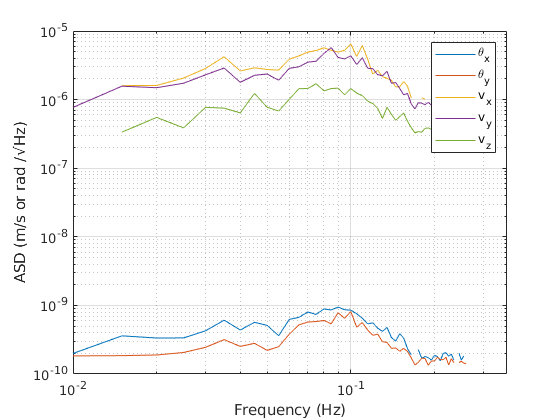


loglog(F,abs(ARX),F,abs(ARY),F,abs(AX),F,abs(AY),F,abs(AZ));
grid on
ylabel('ASD (m/s or rad /\surd{Hz})')
xlabel('Frequency (Hz)')
legend('\theta_x','\theta_y','v_x','v_y','v_z')

In an attempt to cut out frequencies that don't contain signal from the earthquake I applied a amplitude cut tuned by eye. This should be replaced by a threshold on the coherence of the signals and will be in the future.

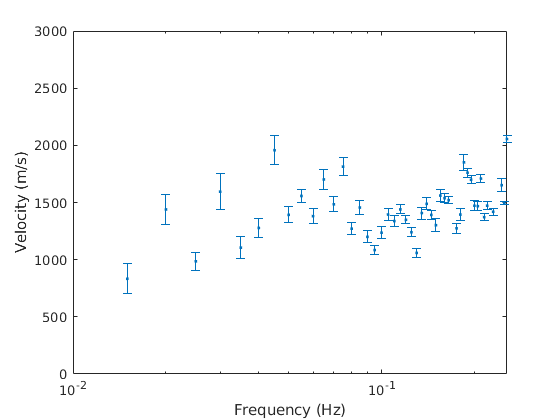

%% Phase Velocity Calculations

in=find(and(or(abs(ARX)>1e-12,abs(ARY)>1e-12),abs(AZ)>5e-10));

v=abs(AZ(in)./sqrt(ARX(in).^2+ARY(in).^2));

errZ=abs(1./sqrt(ARX.^2+ARY.^2).*EZ);
errX= abs(AZ./(ARX.^2+ARY.^2).^(3/2).*ARY.*ERY);
errY=abs(AZ./(ARX.^2+ARY.^2).^(3/2).*ARX.*ERX);
err= sqrt(errZ(in).^2+errX(in).^2+errY(in).^2);

f=F(in);

errorbar(f,v,err,'.');
ylabel('Velocity (m/s)')
xlabel('Frequency (Hz)')
set(gca,'XScale','log');
ylim([0 3000])

This can now be looped through many earthquakes to map out the phase velocity in a wider band. Additionally, the error bars here represent one standard deviation of the cuts but an investigation into distribution of these should be done in the future.

## Rayliegh waves to Densities

The Rayliegh wave phase velocity seems like an esoteric quantity to measure. However, it is related to the velocities of the compressional and tranverse wave velocities ($v_l, v_t$) in a fairly straight forward way. In a flat half space the Rayleigh wave velocity ($\nu$) is the solutions of the following equation [2]:


$$(\nu/v_t)^6-8(\nu/v_t)^4+8(\nu/v_t)^2(3-2 (\frac{v_t}{v_l})^2)-16(1-(\frac{v_t}{v_l})^2)=0$$


Luckily this equation only has one real positive root for physical values of $v_l$ and $v_t$. However, the analytical form of this is horrendous and highly non-linear. Additionally, the ground is not a flat half space but a collection of distinct layers which makes the observed Rayleigh wave velocity actually the average over the layers that the wave penetrates. One clear consequence of this is that the phase velocity is not frequency independent. The measured velocity is determined by the following:


$$\nu=\int_0^\infty \nu(z) A(z) dz$$


Where $z$ is the depth with $z=0$ being the surface of the ground, $\nu(z)$is the the function of Rayleigh wave velocity at a given depth, and $A(z)$ is the attenuation function of the wave which determines the contributions to the average at different depths.

This is clearly going to be difficult to fit with normal methods but we can extract these parameters fairly easily with an optimization algorithm. To do this we choose a given ground model consisting of $n$ layers each with distinct $v_l$, $v_t$, and for every layer except for the last one a depth $d_i$. We then can calculate the dispersion curve for this model and the error between the model curve and the observed curve. We then loop through with some sort of optimization algorithm and then we get a velocity profile.

This can then be quickly converted into a density profile using the empirical relation [3]:


$$\rho=1.6612 v_l-0.4721 v_l +0.067 v_l^3-0.0043 v_l^4+0.000106 v_l^5$$


This is then a point like density profile directly below the location of the station. This is compared to the current method of using arrays of seismometers to measure these profiles which intrinsically have some effective area over which they average. With the continued development of roational seismometers one could imagine arrays of such stations giving the ability of three dimensional density profiles with high spatial reslution only limited by the density of the array.

## References:

- Stefano Maranò, Donat Fäh; Processing of translational and rotational motions of surface waves: performance analysis and applications to single sensor and to array measurements, *Geophysical Journal International*, Volume 196, Issue 1, 1 January 2014, Pages 317–339, [https://doi.org/10.1093/gji/ggt187](https://doi.org/10.1093/gji/ggt187)

- Landau, L D; Pitaevskii, L. P.; Kosevich, A. M.; Lifshitz, E.M. (2012). Theory of Elasticity. London: Butterworth-Heinemann.

- Thomas M. Brocher; Empirical Relations between Elastic Wavespeeds and Density in the Earth's Crust. *Bulletin of the Seismological Society of America* ; 95 (6): 2081–2092. doi: [https://doi.org/10.1785/0120050077](https://doi.org/10.1785/0120050077)